x0 =  [100e9; 60e6; 11];

funciton

fun = @(x) misfit_sig(x, epsilon_exp, t, beam, dsigma);


Stop requested.


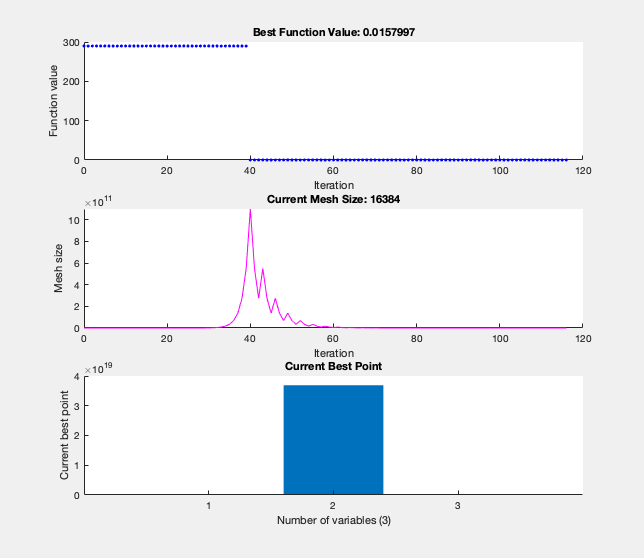

% Set nondefault solver options
options = optimoptions("patternsearch","PlotFcn",["psplotbestf",...
    "psplotmeshsize","psplotbestx"]);

% Solve
[solution,objectiveValue] = patternsearch(fun,x0,[],[],[],[],[],[],[],...
    options);


% Clear variables
clearvars options

function f = objectiveFcn(optimInput)
% Example:
% Minimize Rosenbrock's function
% f = 100*(y - x^2)^2 + (1 - x)^2

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
f = 100*(y - x^2)^2 + (1 - x)^2;
end
